# MRI reconsruction using k-space data with IFFT approach

This example demonstrates how to construct an MR image using k-space data and generate CUDA code with [GPU Coder](https://www.mathworks.com/products/gpu-coder.html). We will use a T1-weighted [dataset](https://ssd.mathworks.com/supportfiles/medical/M4Raw_sample.zip) [1] with dimensions of 256x256x4x18 (4 channels and 18 slices per subject).

The primary goal of this MRI reconstruction approach is to simplify the use of available methods for engineers and medical professionals, enabling them to prototype and deploy CUDA code for faster MRI reconstruction from raw k-space data. This foundational approach involves transforming raw data from the Fourier domain to image space using the IFFT method, followed by the Root Sum of Squares technique to combine coil sensitivities and reconstruct the MRI image for further processing.

[1] Lyu, M., Mei, L., Huang, S. et al. M4Raw: A multi-contrast, multi-repetition, multi-channel MRI k-space dataset for low-field MRI research. Sci Data 10, 264 (2023). [https://doi.org/10.1038/s41597-023-02181-4](https://doi.org/10.1038/s41597-023-02181-4)

**Input k-space data                                                                            Reconstructed MRI image**

 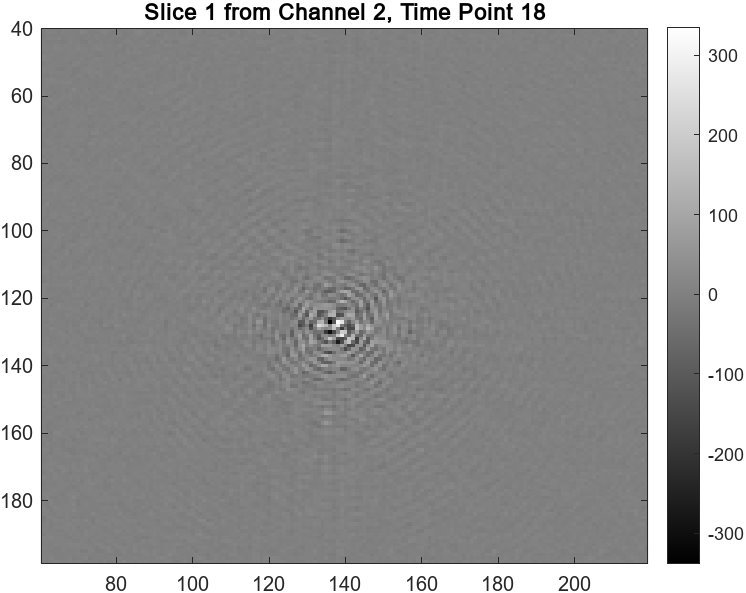                                               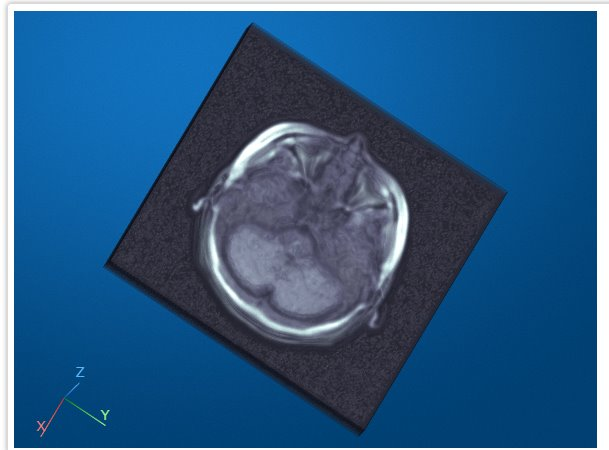

**Load and process Data**

#### Following code snippet carries following steps from data loading till MRI image reconstruction

- Construct File Path: Combines the directory path and file name to create the full file path.

- Extract File Name: Retrieves the file name without its extension.

- Read k-Space Data: Reads the k-space data from the specified dataset path in the HDF5 file.

- Shift k-Space Data: Applies the `ifftshift` function twice to shift the zero-frequency component to the center of the spectrum.

- Convert to Complex: Combines the real and imaginary parts to form a complex k-space data array.

- Inverse FFT: Performs a 2D inverse Fast Fourier Transform (IFFT) on the k-space data to obtain the image in the spatial domain.

- Shift Image Data: Applies the `fftshift` function twice to shift the zero-frequency component back to the corners.

- Combine Coil Sensitivities: Uses the Root Sum of Squares method to combine the coil sensitivity images.

The **Root Sum of Squares (RSS)** method combines the coil sensitivity images by taking the square root of the sum of the squares of the absolute values of the images from each coil. Mathematically, it can be expressed as:


$$\[
\text{RSS} = \sqrt{\sum_{i=1}^{N} |I_i|^2}
\]$$


where:

- *I**i* is the image from the *i*-th coil,

- *N* is the total number of coils.

          9. Squeeze Dimensions: Removes singleton dimensions from the reconstructed image array.

        10. Save Reconstructed Image: Saves the reconstructed image to a .mat file with a modified file name.

dataDir = fullfile(pwd, "data", "inputData");
outDir = fullfile(pwd, "result", "ifftResult");

fileList = dir(fullfile(dataDir, '*.h5'));
for fileIdx = 1:length(fileList)
    filePath = fullfile(dataDir, fileList(fileIdx).name);
    [~, fileName, ~] = fileparts(fileList(fileIdx).name);
    datasetPath = '/kspace';
    
    % Start timing the reconstruction process
    tic;
    
    kspaceData = h5read(filePath, datasetPath);
    kspaceShifted = ifftshift(ifftshift(kspaceData, 1), 2);
    kspace = complex(kspaceShifted.r, kspaceShifted.i);
    imageC = ifft2(double(kspace));
    imageC = fftshift(fftshift(imageC, 1), 2);
    reconImage = sqrt(sum(abs(imageC).^2, 3));
    reconImage = squeeze(reconImage);
    
    % Save the reconstructed image
    save(fullfile(outDir, [fileName, '_reconstructedIFFT.mat']), 'reconImage');
    
    % End timing and display the reconstruction time
    elapsedTime = toc;
    fprintf('Reconstruction time for %s: %.2f seconds\n', fileName, elapsedTime);
end

# Visualization of MRI Reconstruction

Visualizing MRI reconstruction results is crucial for analyzing and interpreting the data. Various visualization techniques can be employed to view and understand the reconstructed images effectively.

**Medical volume datastore **

The [`medicalVolume`](https://www.mathworks.com/help/medical-imaging/ref/medicalvolume.html) function in MATLAB is used to create a medical volume object from image data. This object encapsulates the voxel data and associated metadata, such as the volume's geometry and patient coordinate system

R = medicalref3d(size(reconImage));
medVolCSReconImage =medicalVolume(reconImage,R);
medVolCSReconImage.VolumeGeometry.PatientCoordinateSystem ="LPS+";
voxInfo =medVolCSReconImage.Voxels;
min_val = min(voxInfo(:));
max_val = max(voxInfo(:));
normalized_data = (voxInfo(:) - min_val) / (max_val - min_val);

data =reshape(normalized_data,[256 256 18]);
medVolReconImage= medicalVolume(data,medVolCSReconImage.VolumeGeometry);


## **Visualization Methods**

### Slice View:

Displays individual slices of the 3D reconstructed image, allowing detailed examination of each slice.

sv =sliceViewer(medVolReconImage,Parent=figure)

sv =   sliceViewer with properties:

             SliceDirection: [0 0 1]
                SliceNumber: 10
                     Parent: [1×1 Panel]
                   Colormap: [256×3 double]
               DisplayRange: [0 1]
               ScaleFactors: [1 1 1]
    DisplayRangeInteraction: 'on'


### Volume Rendering

Provides a 3D visualization of the reconstructed image using cinematic rendering, enhancing the depth and detail of the image.

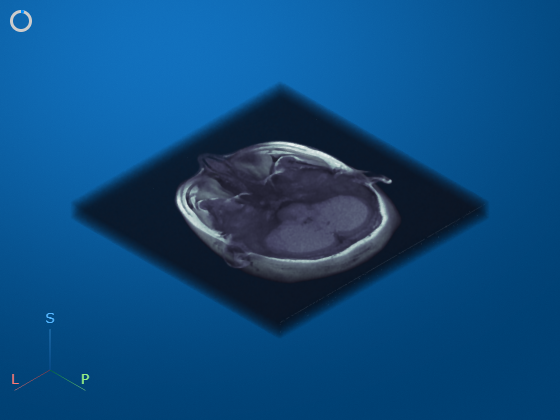

c =bone(20);
volshow(medVolReconImage,RenderingStyle="CinematicRendering",Colormap=c)

### Montage View

Creates a montage of slices from the 3D reconstructed image, offering a comprehensive overview of the entire volume.

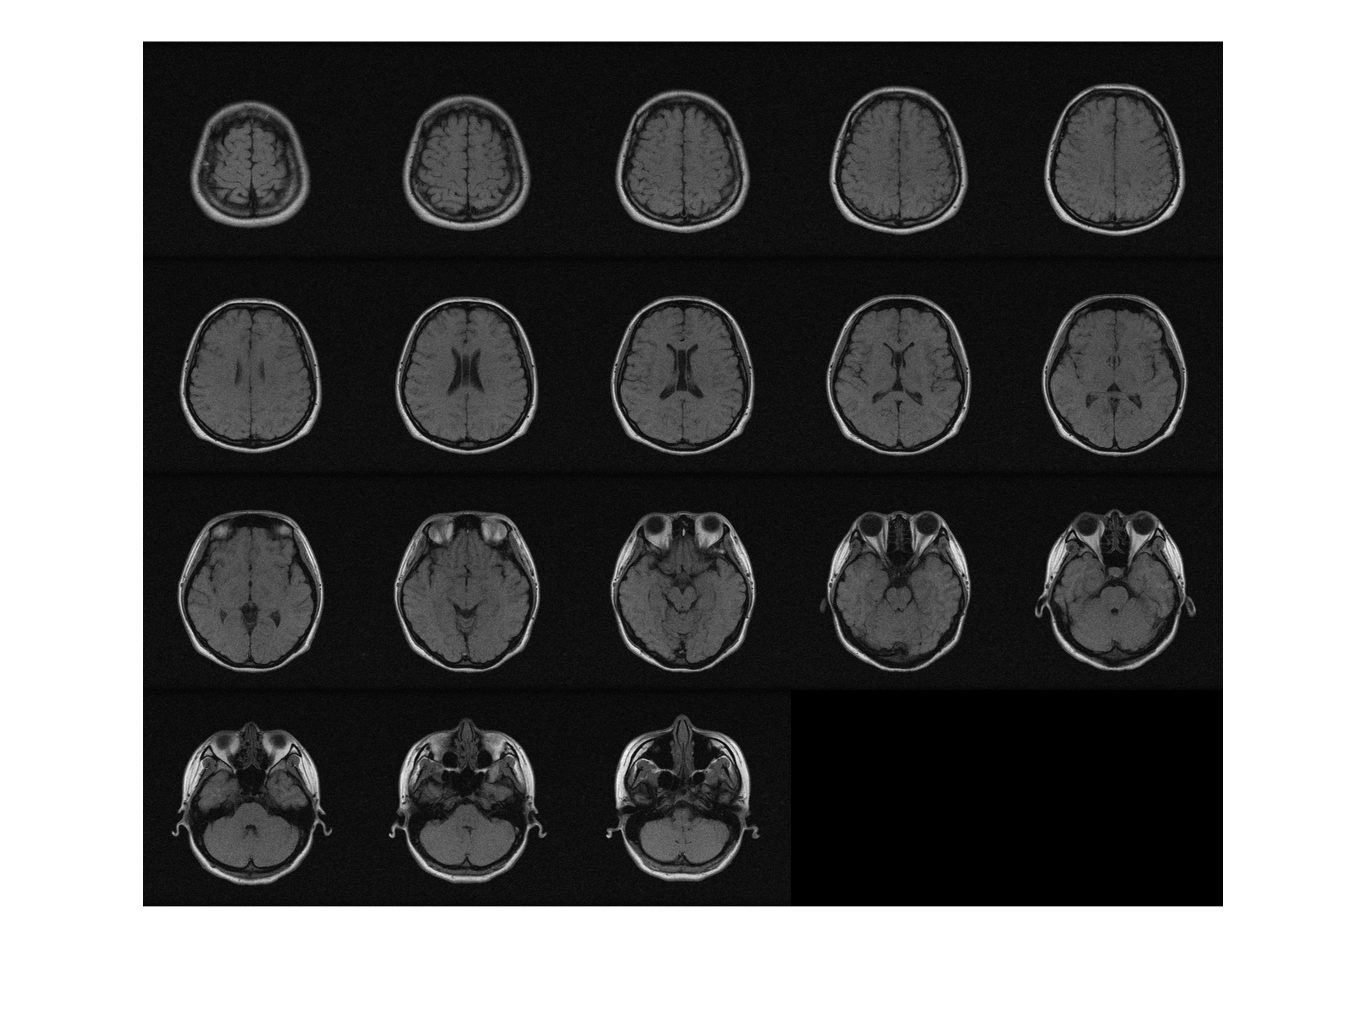

montage(medVolReconImage)